**References**

% Barten, Peter G, Contrast Sensivity of the Human Eye and Its Effects on Image Quality (1999)
% A. B. Watson, "A formula for human retinal ganglion cell receptive field density as a function of visual field location," J. Vis. 14, 1–17 (2014).
% S. J. Daly, "Visible differences predictor: an algorithm for the assessment of image fidelity," in Human Vision, Visual Processing, and Digital Display III, B. E. Rogowitz, ed. (SPIE, 1992), Vol. 1666, p. 2.
% L. N. Thibos, D. L. Still, and A. Bradley, "Characterization of spatial aliasing and contrast sensitivity in peripheral vision," Vision Res. 36, 249–258 (1996).

clear all; 
close all;
clc;

**Variables of Barten CSF Model**

% Frequency range in cpd
u   = 0.1:0.01:100;

% Eccentricity in degrees
e   = 0:10:30;

% Average luminance of the observed object in cd/m^2
L   = 150;

% Field diameter in degrees
D   = 5;

% Signal to Noise ratio
k   = 3;

% Constant for quantom efficiency
eta0 = 0.03;

% constanct for the eye MTF
sigma0 = 0.50;

% eccentricity constant (can be different for various subjects)
eg      = 3.3;

% Spatial frequency above which the lateral inhibition ceases as a function of eccentricity in Fovea
u00     = 7;

% Density of total Retinal ganglion cells in fovea
Ng0       = 33163.2;




### **Plot**

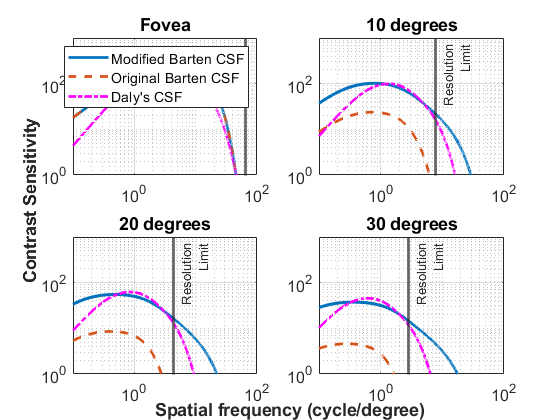

fig = figure;

for i= 1:length(e)
    
    % Andrew Watson formula for temporal midget density
    a         = 0.9851;
    r2        = 1.058;
    re        = 22.14;
    rm        = 41.03;
    Ngm_temporal(i) = Ng0 * (0.8928*(1+e(i)/rm)^-1) * ( a * (1+(e(i)/r2)).^-2 + (1-a) * exp(-e(i)/re));
    
    % Andrew Watson formula for nasal midget density
    a_n       = 0.9729;
    r2_n      = 1.084;
    re_n      = 7.633;
    rm_n      = 41.03;
    Ngm_nasal(i) = Ng0 * (0.8928*(1+e(i)/rm_n)^-1) * ( a_n * (1+(e(i)/r2_n)).^-2 + (1-a_n) * exp(-e(i)/re_n));
    
    % Binocular mode
    Ngm(i)       = mean([Ngm_temporal(i),Ngm_nasal(i)]);
    
    nyquistF(i)  = sqrt(0.5*Ngm(i)/(2*sqrt(3))); 
    
    outputdet(i,:) = bartenDetection(u,e(i),L,D,k,eta0,sigma0,eg,u00);
    outputMC(i,:)  = bartenMC(u,e(i),L,D,k,eta0,sigma0,eg,u00);
    daly(i,:)      = dalyCSF(u,0,L,D^2*pi/4,1,e(i));
    
end

    titles = {'Fovea','10 degrees','20 degrees','30 degrees'};
    
    subplot(2,2,1)
    loglog(u,outputdet(1,:),'-',u,outputMC(1,:),'--',u,daly(1,:),'-.m',LineWidth=2);
    title(titles{1})
    ylim([1 1000]);
    xlim([0.1 100]);
    xline(nyquistF(1),LineWidth=2)
    grid on
    legend('Modified Barten CSF','Original Barten CSF',"Daly's CSF")
    set(gca,'fontsize', 12)

for j = 2:length(e)
    
    subplot(2,2,j)
    loglog(u,outputdet(j,:),'-',u,outputMC(j,:),'--',u,daly(j,:),'-.m',LineWidth=2);
    title(titles{j})
    ylim([1 1000]);
    xlim([0.1 100]);
    xline(nyquistF(j),'-',{'Resolution','Limit'},LineWidth=2);    
    grid on
    set(gca,'fontsize', 12)
    
end

han=axes(fig,'visible','off'); 
han.Title.Visible='on';
han.XLabel.Visible='on';
han.YLabel.Visible='on';
ylabel(han,'Contrast Sensitivity','FontWeight','bold');
xlabel(han,'Spatial frequency (cycle/degree)','FontWeight','bold');
set(gca,'fontsize', 12)